convv = @(i,k,p,s) [(i(1)-k(1)+p(1)+s(1))/s(1) (i(2)-k(2)+p(2)+s(2))/s(2)];
convv([41 41],[15 15],[1 1],[1 1])

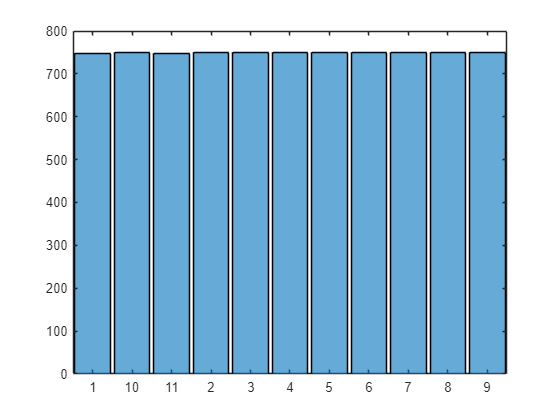

clear;clc;close all
% .mat
allImage = imageDatastore("data\win200_ov160", ...
    "FileExtensions",".mat", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames", ...
    "ReadFcn",@sig2scalogram);
histogram(allImage.Labels,unique(allImage.Labels))

clear;clc
% .jpg
allImage = imageDatastore("data_jpg_28_mag_u", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");
% keep ch1 only (use @myDatastoreFunc)
logic = true(numel(allImage.Files),1);
logic(1:16:end) = false;
allImage.Files(logic) = [];
clear logic

% same data size
logic = true(numel(allImage.Files),1);
[classes,idx] = unique(allImage.Labels);
for i = 1:numel(classes)
    nData(i) = sum(allImage.Labels == classes(i));
end
for i = idx'
    logic(i:i+min(nData)) = false;
end
allImage.Files(logic) = [];
clear logic i idx nData classes
histogram(allImage.Labels,unique(allImage.Labels))

imgSize = size(allImage.read)

imgSize =     57   200    16


[trainDS, testDS] = splitEachLabel(allImage,0.8,"randomized");
nClass = numel(unique(trainDS.Labels))

nClass = 11

% all data
% data = image;
% label = categorical(repmat(["fist1" ;"fist0"],nSample/2,1));
% % spilt
% Xtrain = data(:,:,:,rndIdx(1:nTrainData));
% Ytrain = label(rndIdx(1:nTrainData));
% Xtest = data(:,:,:,rndIdx(nTrainData+1:end));
% Ytest = label(rndIdx(nTrainData+1:end));
% plot(layerGraph(layers))

layers = [
    imageInputLayer(imgSize)

    convolution2dLayer(3,32,Padding="same")
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,64,Padding="same")
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    fullyConnectedLayer(nClass)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('adam',...
    'MiniBatchSize',128,...
    'MaxEpochs',30,...
    'Verbose',1,...
    'ValidationFrequency',20,...
    'ExecutionEnvironment','auto',...
    'Plots','training-progress', ...
    'ValidationData',testDS, ...
    'InitialLearnRate',0.01...
    );

% trainedNet = trainnet(trainDS,layers,"crossentropy",options);
net = trainNetwork(trainDS,layers,options);
% trainedNet = trainNetwork(Xtrain,Ytrain,layers,options);
% mean(classify(trainedNet,testDS) == Ytest)


% [Ypred,p] = classify(trainedNetwork_1,testDS);
% mean(classify(trainedNetwork_1,trainDS)==trainDS.Labels)*100
mean(Ypred==testDS.Labels)*100

ans = 93.9527

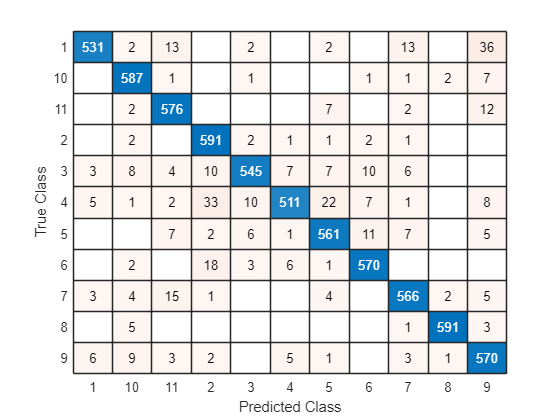

confusionchart(testDS.Labels,Ypred)

datastoreFunc(allImage.Files{1})

allImage.read

function img = myDatastoreFunc(fileName)
    imgFormatName = extractAfter(fileName,'.');
    imgAndChannel = extractBetween(fileName,'img_','.');
    imgNumber = extractBefore(imgAndChannel,'_');
    imgGroupName = extractBefore(fileName,strcat('img_',imgNumber));
    imgGroupName = strcat(imgGroupName,strcat('img_',imgNumber,'_'));
    for ch = 1:16
        img(:,:,ch) = imread(string(imgGroupName) + ch + "." + string(imgFormatName));
    end
end
function Image = sig2scalogram(fileName)
    img = load(fileName).img;
    fb = cwtfilterbank('SignalLength',size(img,1),'VoicesPerOctave',12);
    Image = [];
    c1=[];
    c2=[];
    for ch = 1:size(img,2)
        x = abs(fb.wt(img(:,ch)));
        x = rescale(x); % between [0,1]
        % x = im2uint8(x); % not recommended for .mat (.jpg?)
        % x = imresize(x, imgSize); % resize

        % subplot(221);plot(img(:,ch))
        % subplot(222);imshow(x)
        % subplot(223);imshow(x1)
        % subplot(224);imshow(x2)

        % concat 1
        Image = cat(3,Image,x);

        % concat 2
        % Image = cat(1,Image,x);

        % concat 3
        % if rem(ch,2)==0
        %     c2 = cat(1,c2,x);
        % else
        %     c1 = cat(1,c1,x);
        % end
    end

    % concat 3
    % Image = cat(2,c1,c2);

    % RGB
    % Image = ind2rgb(Image,jet(256));

    % rescale all
    % Image = rescale(Image);

    % imshow(Image)
    % imahow(rescale(Image))
end